# Effect of Feedback on Pole Locations

Consider the feedback control system.

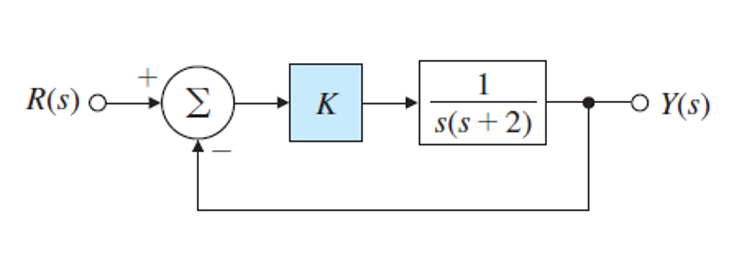

The plant is very similar to a rotating mass with some viscous damping.  A system like


$$G(s) = \frac{\kappa}{s(Js + b)}$$


but the coefficients have been chosen to make it look "nice."

G = tf(1,[ 1 2 0 ])

G =
 
      1
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



The controller uses proportional (P) control; the controller is a proportional gain $K$.

K = 39.5

K = 39.5000

We can calculate it analytically and get the transfer function


$$\frac{y(s)}{r(s)} = T(s) = \frac{K}{s^2 + 2s + K}$$


We want to calculate the closed-loop system using MATLAB.

## Using MATLAB to build the closed-loop transfer function

### A naive approach

Because this is unity feedback (the feedback path is 1), the forward path and the loop-gain are the same.

L = K*G

L =
 
    39.5
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



The closed-loop transfer function is

T = L/(1+L)

T =
 
         39.5 s^2 + 79 s
  -----------------------------
  s^4 + 4 s^3 + 43.5 s^2 + 79 s
 
Continuous-time transfer function.



zpk(T)

ans =
 
        39.5 s (s+2)
  -------------------------
  s (s+2) (s^2 + 2s + 39.5)
 
Continuous-time zero/pole/gain model.



WAIT!  There is an $s$ and $(s + 2)$ term in the numerator and denominator.  Why didn't MATLAB cancel them out?  Ugh...long story.  We can remove them this way:

T = minreal(T)

T =
 
        39.5
  ----------------
  s^2 + 2 s + 39.5
 
Continuous-time transfer function.



The **minreal** function makes a "minimum realization", which is a fancy way of saying it cancels poles and zeros if it can.

### A better approach

We could also build the system this way

L = series(K,G)

L =
 
    39.5
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



T = feedback(L,1)

T =
 
        39.5
  ----------------
  s^2 + 2 s + 39.5
 
Continuous-time transfer function.



The **feedback** command creates a feedback connection with the first entry being the forward path, and the second entry being the feedback path.

If we use the series and feedback commands of MATLAB, then MATLAB knows how to cancel terms correctly.

## Getting the poles and zeros

We might want to get the poles (certainly) and zeros (maybe but there are none for this problem) of the closed-loop system.  There are several ways to do that.

### Using damp

The command **damp** gives the poles of a transfer function.  It shows the complex values of all poles, the damping ratio (real poles have $\zeta = 1$), the natural frequency in (rad/second), and the time constant, which is $\tau = 1/\sigma$.

damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+00 + 6.20e+00i     1.59e-01       6.28e+00         1.00e+00    
 -1.00e+00 - 6.20e+00i     1.59e-01       6.28e+00         1.00e+00    


### Using zpkdata

The command **zpkdata** returns the zeros, poles, and gain of a transfer function written in the form


$$T(s) = k \frac{(s - z_1) \cdots (s-z_m)}{(s - p_1) \cdots (s - p_n)}$$


[z,p,k] = zpkdata(T,'v');
disp('The poles found using zpkdata command.')

The poles found using zpkdata command.


disp(p)

  -1.0000 + 6.2048i
  -1.0000 - 6.2048i



### Using tfdata and finding the roots

We can get the numerator and denominator polynomials of $T$ and then find the roots of those polynomials.

[numerator,denominator] = tfdata(T,'v');
disp(denominator)

    1.0000    2.0000   39.5000



p = roots(denominator)

p =   -1.0000 + 6.2048i
  -1.0000 - 6.2048i


disp('The poles found using the roots of the denominator.')

The poles found using the roots of the denominator.


disp(p)

  -1.0000 + 6.2048i
  -1.0000 - 6.2048i



## Plot the pole-zero map and step response

Let's look at $T(s)$ in a pole-zero map.

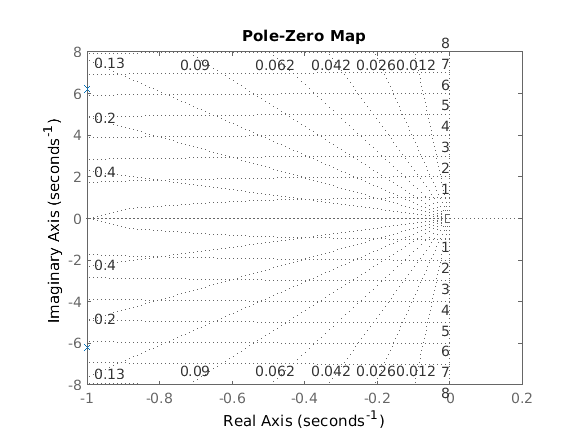

pzplot(T)
grid on

Sometimes you have to squint and look close to find the $\times$ where the poles are.

Here is the impulse response.

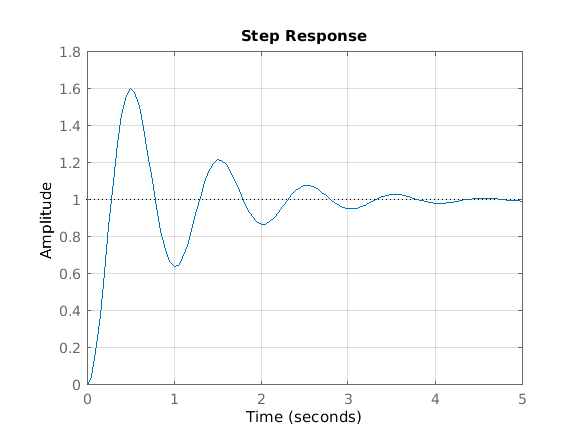

Tfinal = 5;
step(T,Tfinal)
grid on

## Chosing $K$ for a particular specification

We might want to choose $K$ so that the pole have a certain damping or natural frequency.  The characteristic equation is

$s^2 + 2 s + K
 = s^2 + 2 \zeta \omega_n s + \omega_n^2$.

Matching coefficients we see that the real part of the poles is fixed


$$\sigma = \zeta \omega_n = 1$$


and that 

$\omega_n^2 = K$ and


$$\zeta = \frac{1}{\sqrt{K}}$$


Clearly, by picking $K$ we can specify either $\zeta$ or $\omega$ but not both.  (This is true only for this problem.  With more complicated controllers you can place the poles anywhere you like.)

### Specifying the damping ratio

#### Under damped

What value of $K$ makes the closed-loop damping ratio equal to $0.1$?  Enter it above, look at the pole-zero map, and the response.  Does this all make sense?

#### Critically damped

What value of $K$ makes the closed-loop system critically damped?  Enter it above and look at the response.

#### Over damped

Choose a value of $K$ below the critically damped value and see what the response looks like.  Where are the poles?

Note that when the system is over damped there are two real poles so that


$$s^2 + 2 s + K \\
\qquad = (s + a)(s + b) \\
\qquad = s^2 + (a + b)s + ab
$$


Now 

$K = ab$ and

$2 = a + b$ or the average value of the poles $\frac{a + b}{2} = 1$.

## Specifying the natural frequency

#### Under damped

What value of $K$ make the closed-loop natural frequency equal to $2\pi$ rad/s (1 Hz)?  Enter it above and look at the response.  Does the response make sense?

What happens to the damping ratio as you increase the closed-loop natural frequency?  What happens if you decrease it?

#### Critically damped

What value of $K$ makes the closed-loop natural frequency equal to 1 rad/s?  How does this compare to the critically damped value you calculated above?  What is the damping ratio for this value of $K$? 

#### Over damped

Does it make sense to talk about natural frequency when a second order system is overdamped?  